# Train a DDPG Agent for the Warehouse Robot

## Define the environment

Discrete states and actions. Six continuous numeric state variables. Two continuous actions in the range [-1 1].

obsInfo = rlNumericSpec([6 1]);
actInfo = rlNumericSpec([2 1],"UpperLimit",1,"LowerLimit",-1);

env = rlSimulinkEnv("whrobot","whrobot/controller",obsInfo,actInfo);
env.ResetFcn = @randomstart;

## Define the agent

A DDPG agent consists of a deterministic actor and a Q-value critic:

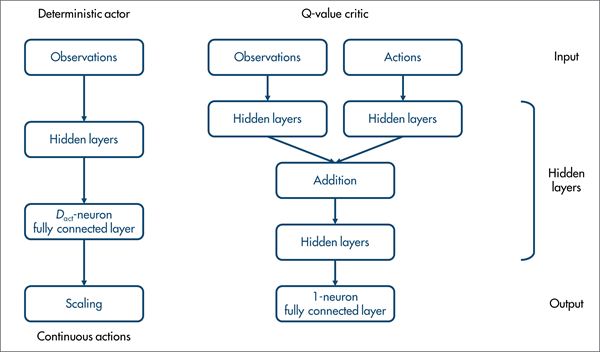

#### Create the actor

Define the network for a deterministic actor. 6-D input, 2-D output with tanh scaling ([-1 1]).

actnet = [featureInputLayer(6,"Name","obs")
    fullyConnectedLayer(100,"Name","fc1")
    reluLayer("Name","relu1")
    fullyConnectedLayer(100,"Name","fc2")
    reluLayer("Name","relu2")
    fullyConnectedLayer(100,"Name","fc3")
    reluLayer("Name","relu3")
    fullyConnectedLayer(2,"Name","act")
    tanhLayer("Name","scact")];

Define options and create the actor.

opts = rlRepresentationOptions("LearnRate",5e-5,"GradientThreshold",10);
actor = rlDeterministicActorRepresentation(actnet,obsInfo,actInfo,"Observation","obs","Action","scact",opts);

#### Create a critic

Define the network. Q-value networks have two paths that are merged. Observation path has 6-D input, action path has 2-D input. The observation path also contains the layers for the merged path, which ends with a single-neuron output (for the Q value).

obsPath = [featureInputLayer(6,"Name","obs")
    fullyConnectedLayer(100,"Name","fc1")
    reluLayer("Name","relu1")
    fullyConnectedLayer(100,"Name","fc2")
    additionLayer(2,"Name","add")
    reluLayer("Name","relu2")
    fullyConnectedLayer(100,"Name","fc3")
    reluLayer("Name","relu3")
    fullyConnectedLayer(1,"Name","value")];
actPath = [featureInputLayer(2,"Name","act")
    fullyConnectedLayer(100,"Name","fcact")];

Join the input paths at the addition layer.

valnet = layerGraph(obsPath);
valnet = addLayers(valnet,actPath);
valnet = connectLayers(valnet,"fcact","add/in2");

Create the critic (with the same options as the actor).

critic = rlQValueRepresentation(valnet,obsInfo,actInfo,"Observation","obs","Action","act",opts);

#### Create the agent

dt = 0.25;
opts = rlDDPGAgentOptions("SampleTime",dt,"ExperienceBufferLength",1e6,"MiniBatchSize",128);
agent = rlDDPGAgent(actor,critic,opts);

## Train the agent

Check to train agent from scratch.

dotraining = false;
maxsteps = round(30/dt);  % max episode time of 30s (simulation time)
clear plotRobot           % make sure visualization starts fresh   

Train agent or load pretrained agent from file. The pretrained agent `trainedNN` was trained for *NN*$\times 10^3$ episodes.

if dotraining
    opts = rlTrainingOptions( ...
        "MaxStepsPerEpisode",maxsteps, ... 
        "MaxEpisodes",50000, ...
        "ScoreAveragingWindowLength",50, ...
        "StopTrainingCriteria","AverageReward", ...
        "StopTrainingValue",2);
    info = train(agent,env,opts);
else
    load trainedDDPG
    agent = trained15;
end

## Evaluate the agent

Run multiple simulations.

numsim = 20;
simout = sim(agent,env,rlSimulationOptions("MaxSteps",maxsteps,"NumSimulations",numsim))

simout = 20×1 struct array with fields:
    Observation
    Action
    Reward
    IsDone
    SimulationInfo

Episodes can end because (1) the robot succeeded, (2) the robot crashed into the shelves, (3) the episode reached the `MaxSteps` limit.

Determine which episodes were terminated (vs ran to `MaxSteps` limit). Then determine which of those were successful terminations (positive reward).

completed = arrayfun(@(x) any(x.IsDone.Data==1),simout);
succeeded = arrayfun(@(x) x.Reward.Data(x.IsDone.Data==1)>0,simout(completed));

Get the counts from each group.

Nsuccess = nnz(succeeded)

Nsuccess = 20

Ncrash = nnz(completed) - Nsuccess

Ncrash = 0

Nnoresult = numsim - nnz(completed)

Nnoresult = 0

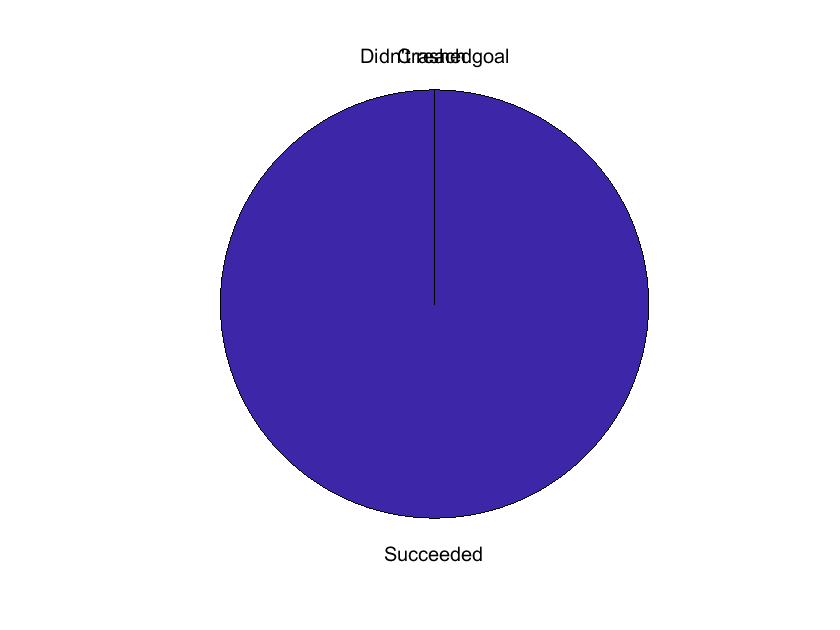

pie([Nsuccess;Ncrash;Nnoresult],[],["Succeeded","Crashed","Didn't reach goal"])

Get the time taken for successful runs.

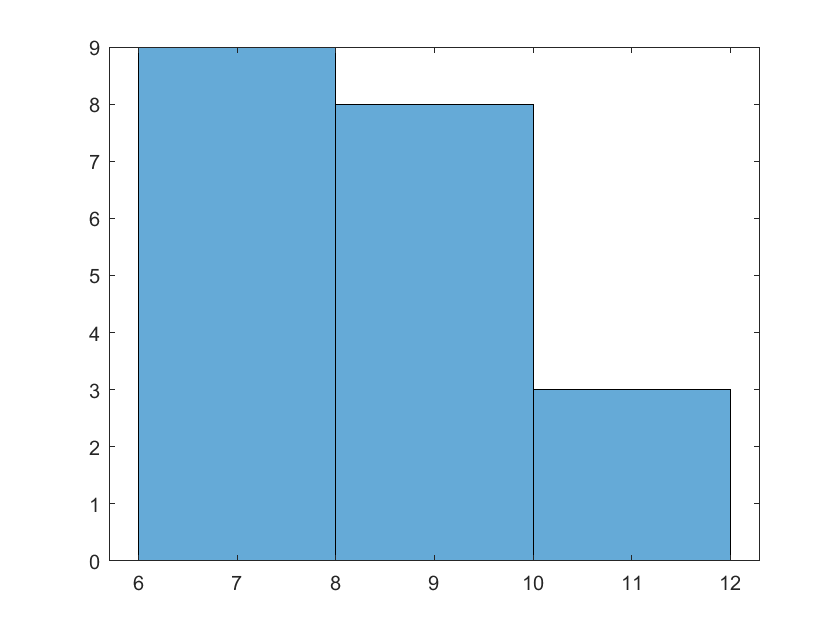

T = arrayfun(@(x) x.IsDone.Time(end),simout(succeeded));
histogram(T)

mean(T)

ans = 8.0750